# Pulse detector test bench (step 1)

This test bench creates a reference pulse detection algorithm, simulates the Simulink model implementation, and compares the Simulink result to the MATLAB reference.

## Create reference algorithm & parameters

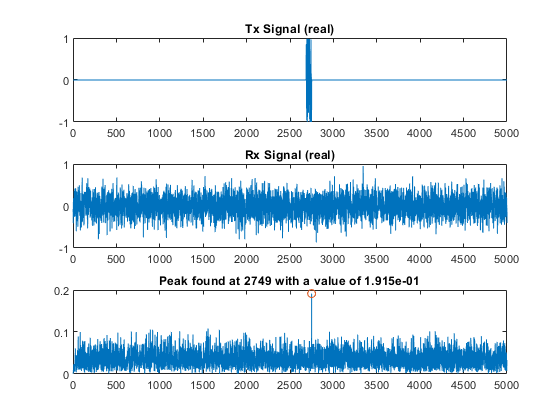

pulse_detector_reference;

## Simulate model and compare results to reference

if iscolumn(CorrFilter)
    CorrFilter = transpose(CorrFilter); % need row vector for filter block
end
SimTime = length(RxSignal) + WindowLen;

% Simulate model
sim('pulse_detector_v1')

% Correlation filter output
FilterOutSL = squeeze(logsout.getElement('filter_out').Values.Data);
compareData(real(FilterOut),real(FilterOutSL),{2 3 1},'ML vs SL correlator output (re)');


Maximum error for ML vs SL correlator output (re) out of 5000 values
 6.938894e-17 (absolute), 3.736211e-14 (percentage)


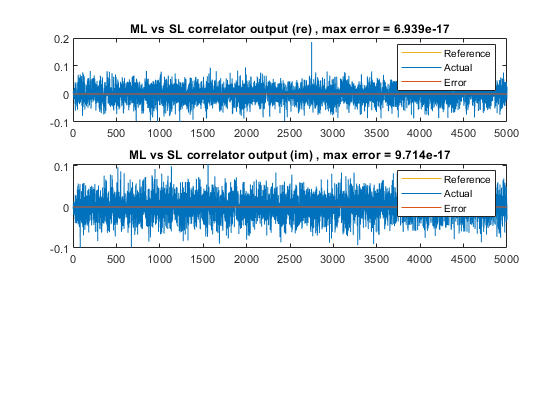


Maximum error for ML vs SL correlator output (im) out of 5000 values
 9.714451e-17 (absolute), 9.285262e-14 (percentage)


compareData(imag(FilterOut),imag(FilterOutSL),{2 3 2},'ML vs SL correlator output (im)');


% Magnitude squared output
MagSqSL = squeeze(logsout.getElement('mag_sq_out').Values.Data);
compareData(MagSqOut,MagSqSL,{2 3 3},'ML vs SL mag-squared output');

% Peak value
MidSampleSL = squeeze(logsout.getElement('mid_sample').Values.Data);
Detected = squeeze(logsout.getElement('detected').Values.Data);
PeakSL = MidSampleSL(Detected>0);

fprintf('\nPeak location = %d, magnitude = %.3d using global max\n',location,peak);
fprintf('Peak location = %d, mag-squared = %.3d using local max\n',location_2,peak_2);
fprintf('Peak mag-squared from Simulink = %.3d, error = %.3d\n', PeakSL,abs(peak_2-PeakSL));